# Initialize

img_path = "images/";

## Trading Card Domain

I decided to use images of physical trading cards (e.g. pokemon) as I would like to eventually create an algorithm to separate real and fake cards

figure;
img_pokemon_pika = imread(img_path + "pokemon_pikachu.png");
img_pokemon_pika_g = rgb2gray(img_pokemon_pika);
%img_pokemon_tepig = imread(img_path + "pokemon_tepig.png");
subplot(1, 2, 1); imshow(img_pokemon_pika); title("original");

### Segment Card from Background

First we make sure we isolate the card from the rest of the background

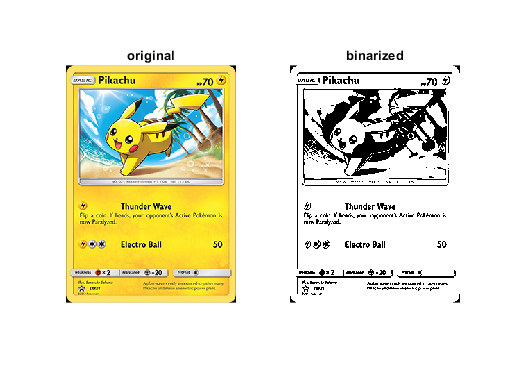

% Use other photo (now card is already isolated)

% Binarize image
img_bw = imbinarize(img_pokemon_pika_g);
subplot(1, 2, 2); imshow(img_bw); title("binarized");

### Segment Name

The name of the pokemon will always appear at the top of the card. Therefore, extract all the text possible from the card and retrieve the text on the top-most left area.

figure;

#### crop to area of interest

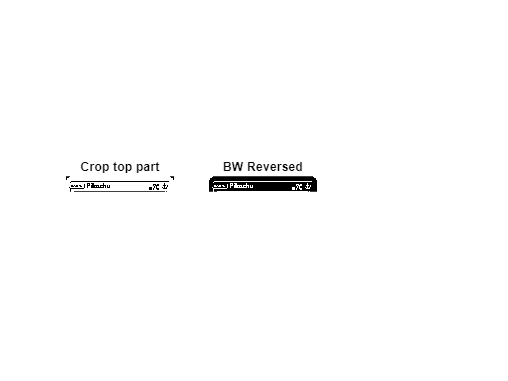

crop_rec = [0.5 0.5 245 34]; % Based on estimated values from imtool
img_bw_cropped = imcrop(img_bw, crop_rec);
subplot(1, 3, 1); imshow(img_bw_cropped); title("Crop top part");

% reverse as to assign the text as the foreground
img_bw_cropped_rev = imcomplement(img_bw_cropped);
subplot(1, 3, 2); imshow(img_bw_cropped_rev); title("BW Reversed");

#### extract the text

nr_of_iter = 10;

% Snakes
%mask_contour_region = zeros(size(img_bw_cropped));
%mask_contour_region(2:end - 2,2:end - 2) = 1;
%img_snakes = activecontour(img_bw_cropped, mask_contour_region, nr_of_iter);
%subplot(1, 3, 2); imshow(mask_contour_region); title('Contour Location');
%subplot(1, 3, 3); imshow(img_snakes); title('Iter: ' + 100);

% Region properties
%neighbour_connectivity = 8;
%CC = bwconncomp(img_bw_cropped, neighbour_connectivity)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [35 245]
      NumObjects: 6
    PixelIdxList: {[7139×1 double]  [4×1 double]  [687]  [4×1 double]  [2×1 double]  [18×1 double]}


%S = regionprops(CC,'Centroid')

S = 6×1 struct array with fields:
    Centroid
